Both transmitters transmit at 10 GHz, and we model their signal bandwidth as 400 MHz. These are the operating parameters of the receive radio.

fc = 10e9;
fsBaseband = 400e6;

## Transmit Signals

The signal of interest is an FM audio signal. We are using this kind of signal to demonstrate the transmission of audio data, but any kind of waveform could be used.

We read the audio signal from a default matlab audio file and create the signal of interest using the FM Modulator.

[y, fsAudio] = audioread('guitartune.wav');
modulator   = comm.FMModulator(SampleRate=fsBaseband,FrequencyDeviation=fsBaseband/3);
soi = modulator(y);

We create a complex noise signal to create interference across the entire bandwidth.

interference = randn(length(soi),1,like=1i);

We compare the transmit and receive spectrums in the frequency domain.

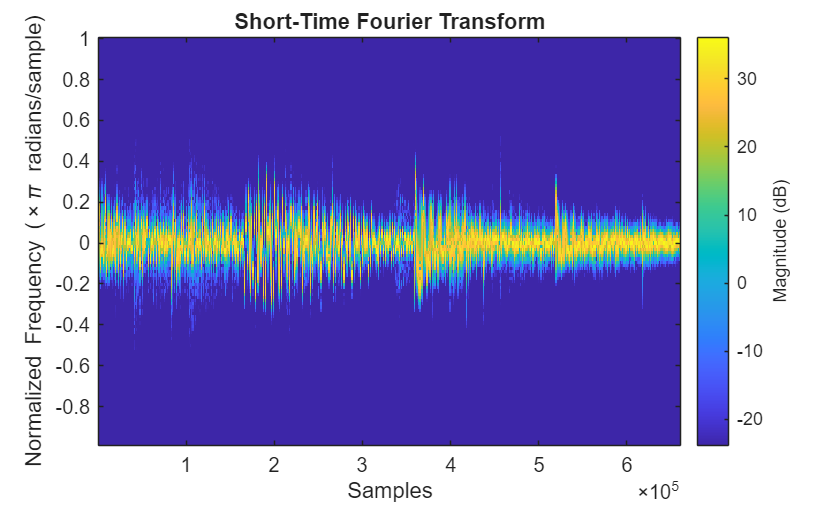

stft(soi);

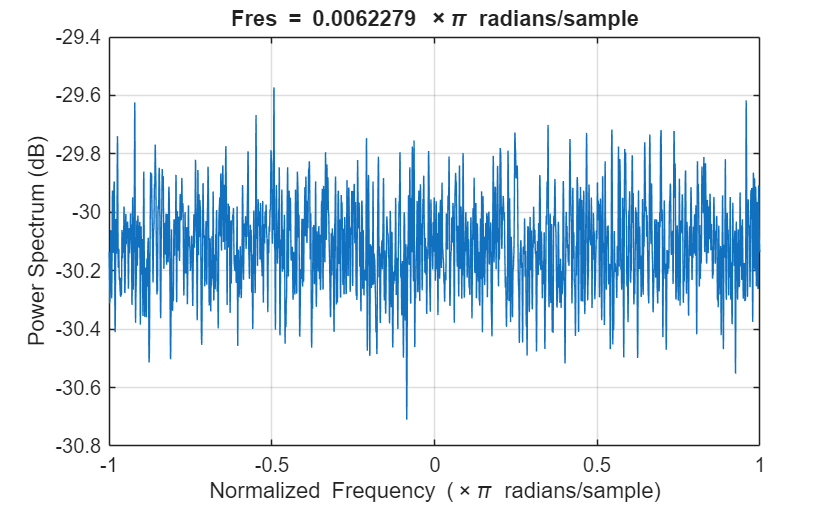

pspectrum(interference);

## Transmit Antennas

The transmitter transmitting the signal of interest and the transmitter transmitting the interference are both modelled as transmitting with an isotropic radiation pattern.

soiTransmitter = phased.IsotropicAntennaElement;
interferenceTransmitter = phased.IsotropicAntennaElement;

The antenna pattern of an isotropic element is uniform in all directions.

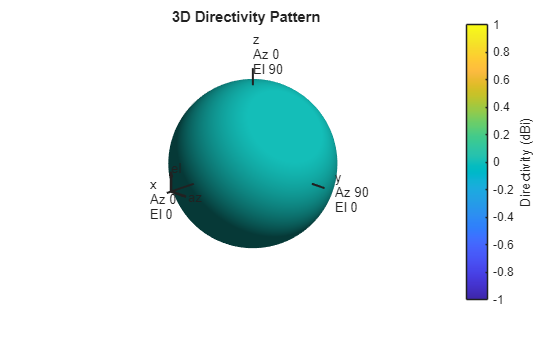

soiTransmitter.pattern(fc);

## Signal Radiation

## Receive Array

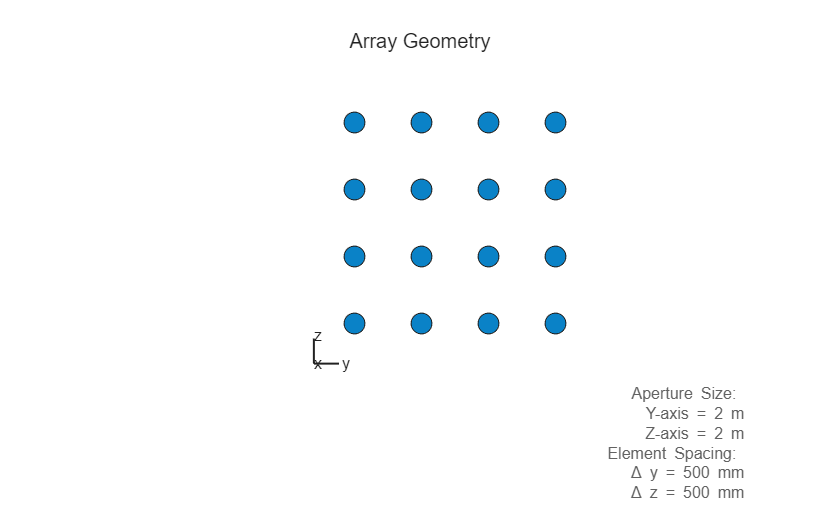

array = phased.URA(Size=[4 4]);
viewArray(array);